clear

% Load the epocheddata.
%load data/smilefrown1filt0p5notch56t64epochs.mat
%load data/smilefrown2filt0p5notch56t64epochs.mat
%load data/smilefrown2filt0p5notch56t64p120epoch.mat
%load data/run15filt0p5doublenotch56t64a120epochs.mat
load data/smilefrownangryblinkS1filt0p5notch56t64epochs.mat

EEG.timessec = EEG.times./1000; %version of times in seconds, useful for signal processing

load data/colormapjetwhite.mat; %loads cmapwj to do a colormap with white instead of green for jet


% Create a new categorical variable for easier manipulation.
% Note, this will be inaccurate if you select a subset of the data without
% subsetting this.
for epoch = 1:EEG.trials
    for i = 1:length(EEG.epoch(epoch).eventlatency)
        if EEG.epoch(epoch).eventlatency{i} == 0
            EEG.epochlabelscat{epoch} = EEG.epoch(epoch).eventtype{i};
        end
    end
end
EEG.epochlabelscat = categorical(EEG.epochlabelscat);
%make an array of all possible labels of events in your data
availableeventlabels = unique(EEG.epochlabelscat)

availableeventlabels = 1×5 categorical array
     A pressed      B pressed      F pressed      S pressed      U pressed 


%We'll use this to index which epochs we want


Do any additional filtering or trial baseline removal that you want (currently another high pass at 20 hz) and also find power first


origEEGdata = EEG.data;
for channel =1:size(EEG.data,1)
    % First, save the power in the frequency comain
    [EEG.freqcalcs.P(channel,:,:),EEG.freqcalcs.F] = pspectrum(squeeze(EEG.data(channel,:,:)),EEG.timessec);
    
    
    %Trial by trial baseline removal (can also do pre-event baseline removal
    %instead
    EEG.data(channel,:, :) = EEG.data(channel,:, :) - mean(EEG.data(channel,:, :),2);
    
    % additional filtering (might want to do this with the continuous data
    % instead, if you find somethign you like)
    %EEG.data(channel,:, :) = highpass(squeeze(EEG.data(channel,:, :)),20,EEG.srate);
end


Now we'll do some calculations to either compare two conditions (or just do a singular one) [could improve this by taking more than 2]. We'll store this in some data structures.

condnames = {"S pressed", "F pressed"};
channels = 1:2;

clear condstruc idxtrials 
for c = 1:length(condnames)
    condname = condnames{c}
    idxtrials = find(EEG.epochlabelscat==condname);
    
    
    for ch = 1:length(channels)
        channel = channels(ch); % in case the channel order isn't linear
        
        % Mean of timecourse
        condstruc(c,ch).meantimecourse = mean(squeeze(EEG.data(channel,:, idxtrials)),2); 
        condstruc(c,ch).stdtimecourse = std(squeeze(EEG.data(channel,:,idxtrials)),0,2);  
        condstruc(c,ch).semtimecourse = condstruc(c,ch).stdtimecourse./sqrt(length(idxtrials)); % Compute 'Standard Error Of The Mean'
        condstruc(c,ch).CI95 = tinv([0.025 0.975], length(idxtrials)-1); % Calculate 95% Probability Intervals Of t-Distribution (might do z intead, largely in consequential)
        condstruc(c,ch).yCI95timecourse = bsxfun(@times, condstruc(c,ch).semtimecourse, condstruc(c,ch).CI95(:)');              % Calculate 95% Confidence Intervals
        
        for i  = 1:length(idxtrials)
            [condstruc(c,ch).cfs(i,:,:),condstruc(c,ch).frq] = cwt(double(EEG.data(channel,:, idxtrials(i))),EEG.srate,'FrequencyLimits',[2 120]);
        end
        % tms is replaced by EEG.timessec (unless you move to a reduced
        % time window)
        %tms = EEG.times./1000; % time axes in seconds% (0:numel(double(EEG.data(channel,:, idxtrials(1))))-1)/EEG.srate);
        
        condstruc(c,ch).meancfs = squeeze(mean(abs(condstruc(c,ch).cfs),1)); %adding an abs here to get magnitude of a complex number
        condstruc(c,ch).stdcfs = squeeze(std(abs(condstruc(c,ch).cfs))); % may actually want to do the stdev across all time w/in a freq too
    end
end

condname = "S pressed"

condname = "F pressed"

Make plots of individual conditions and channels (must run section above first)

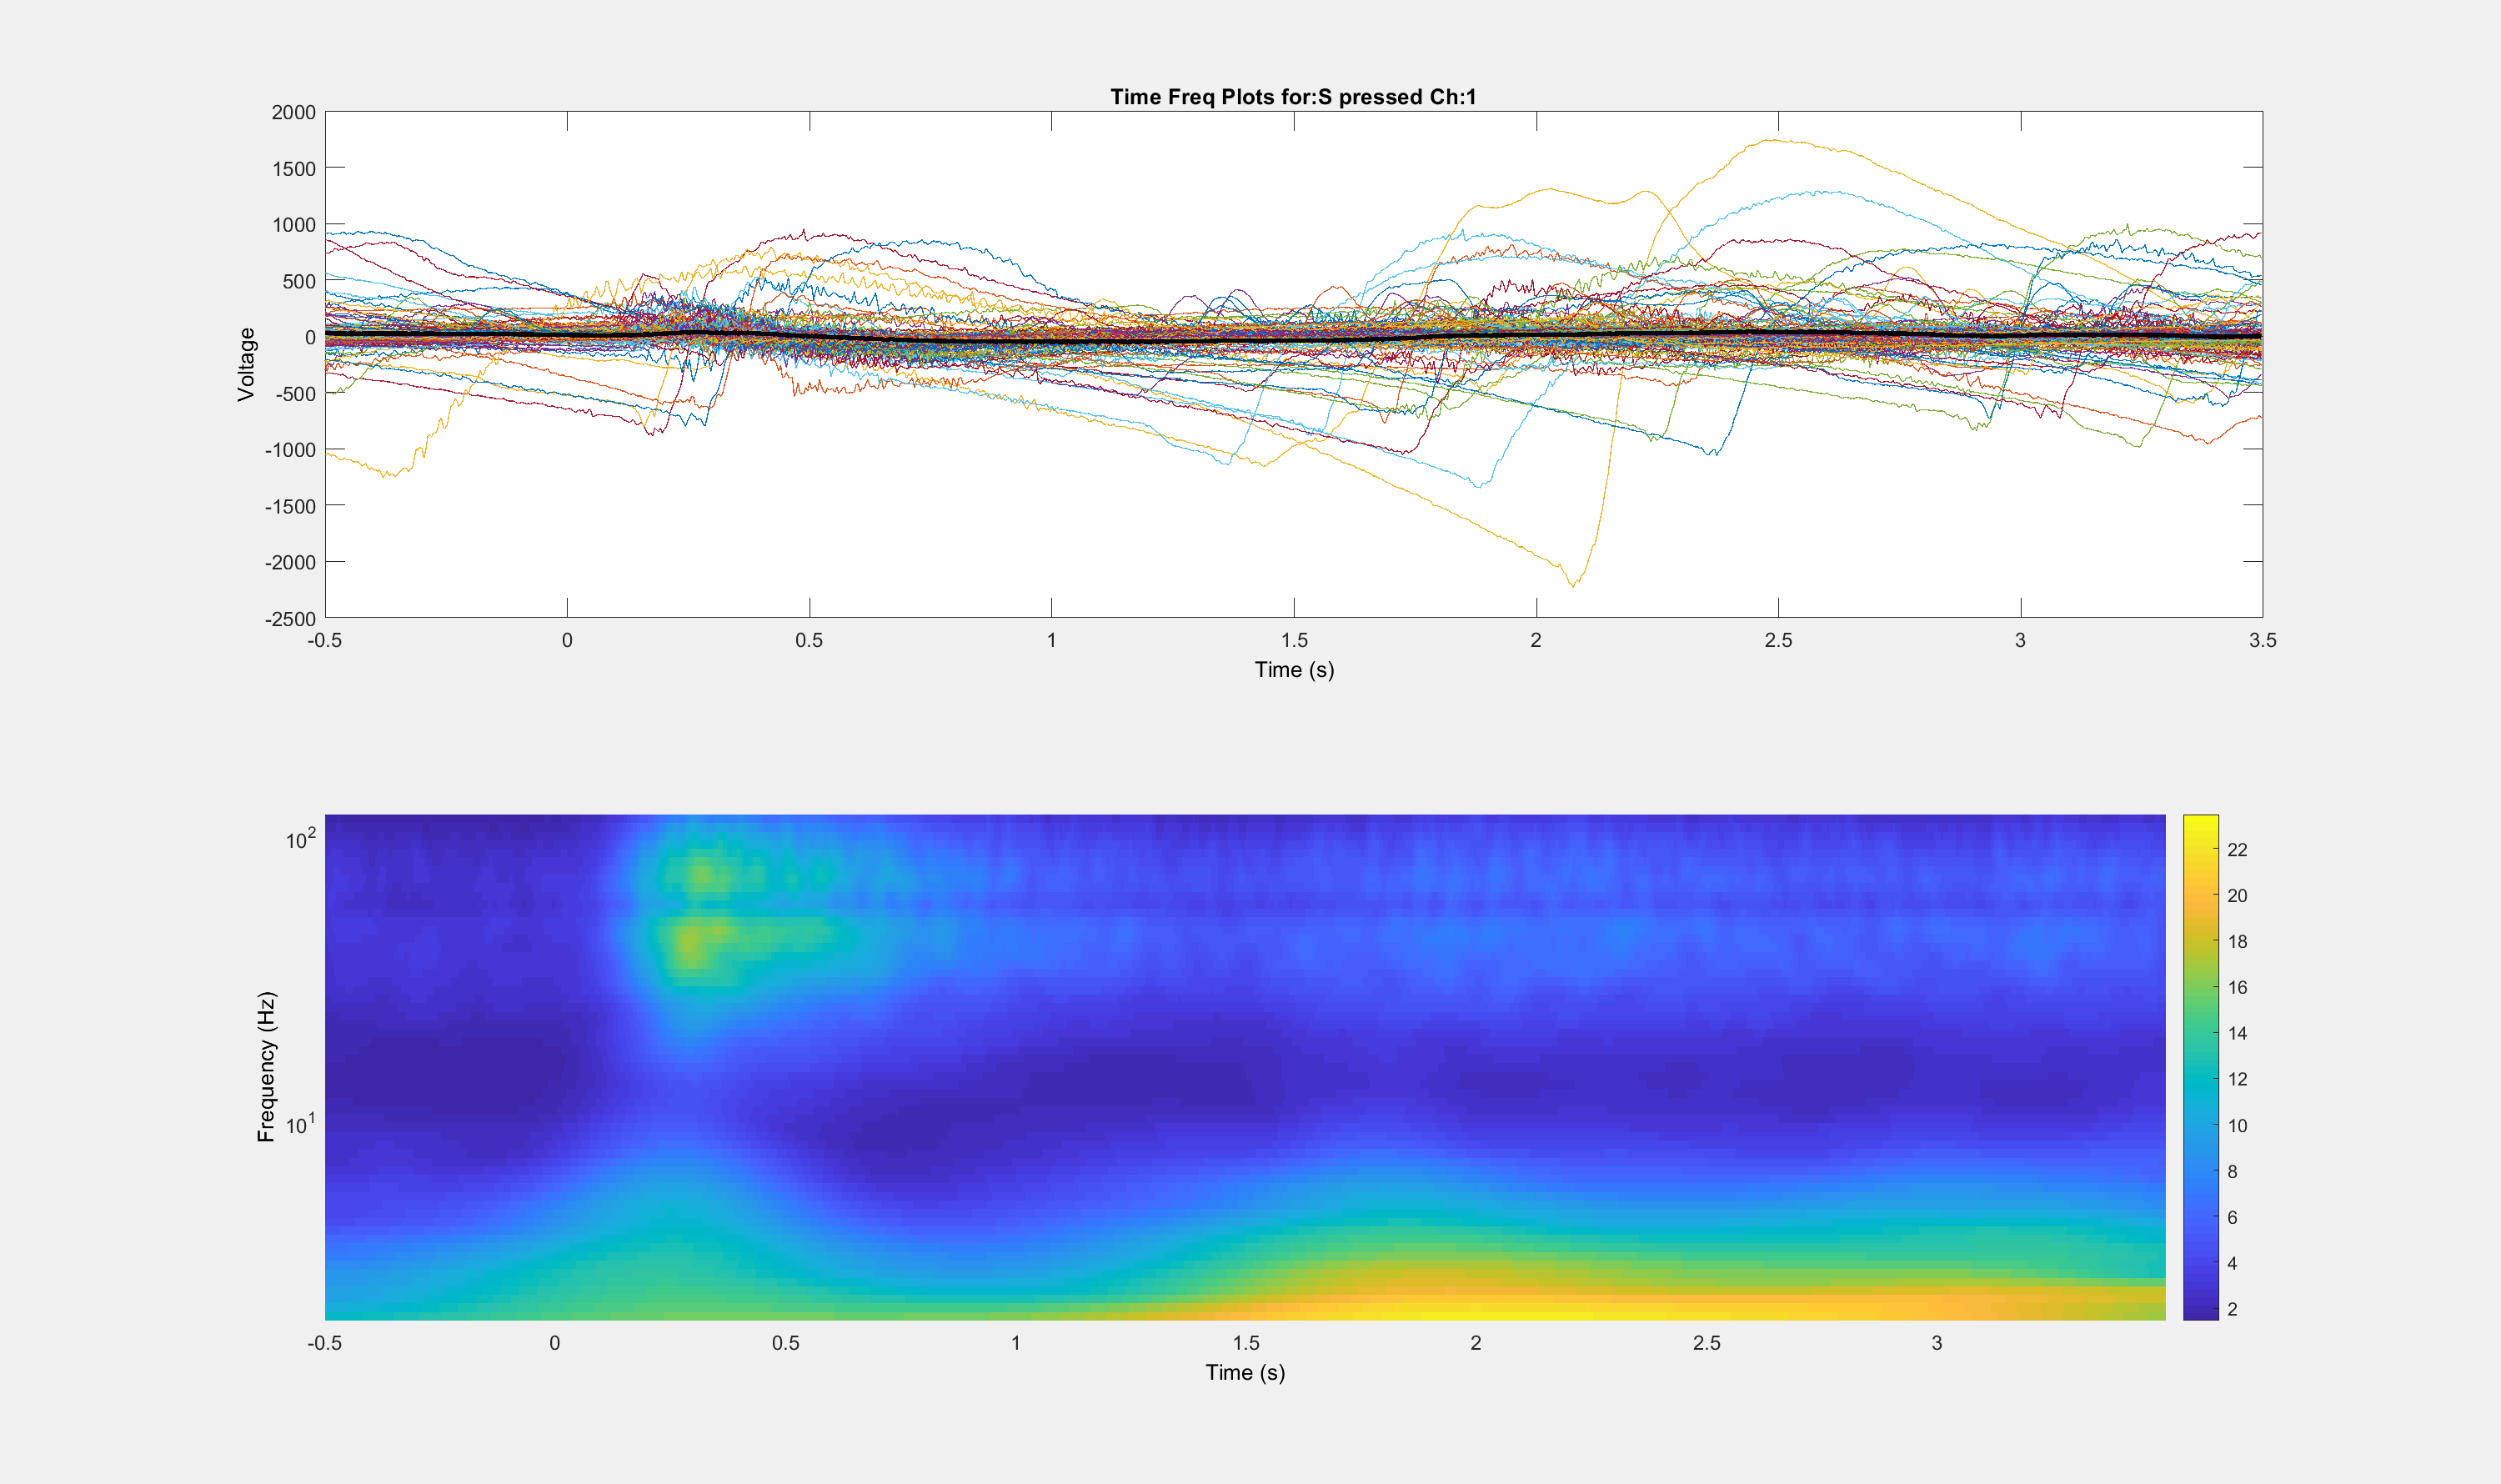

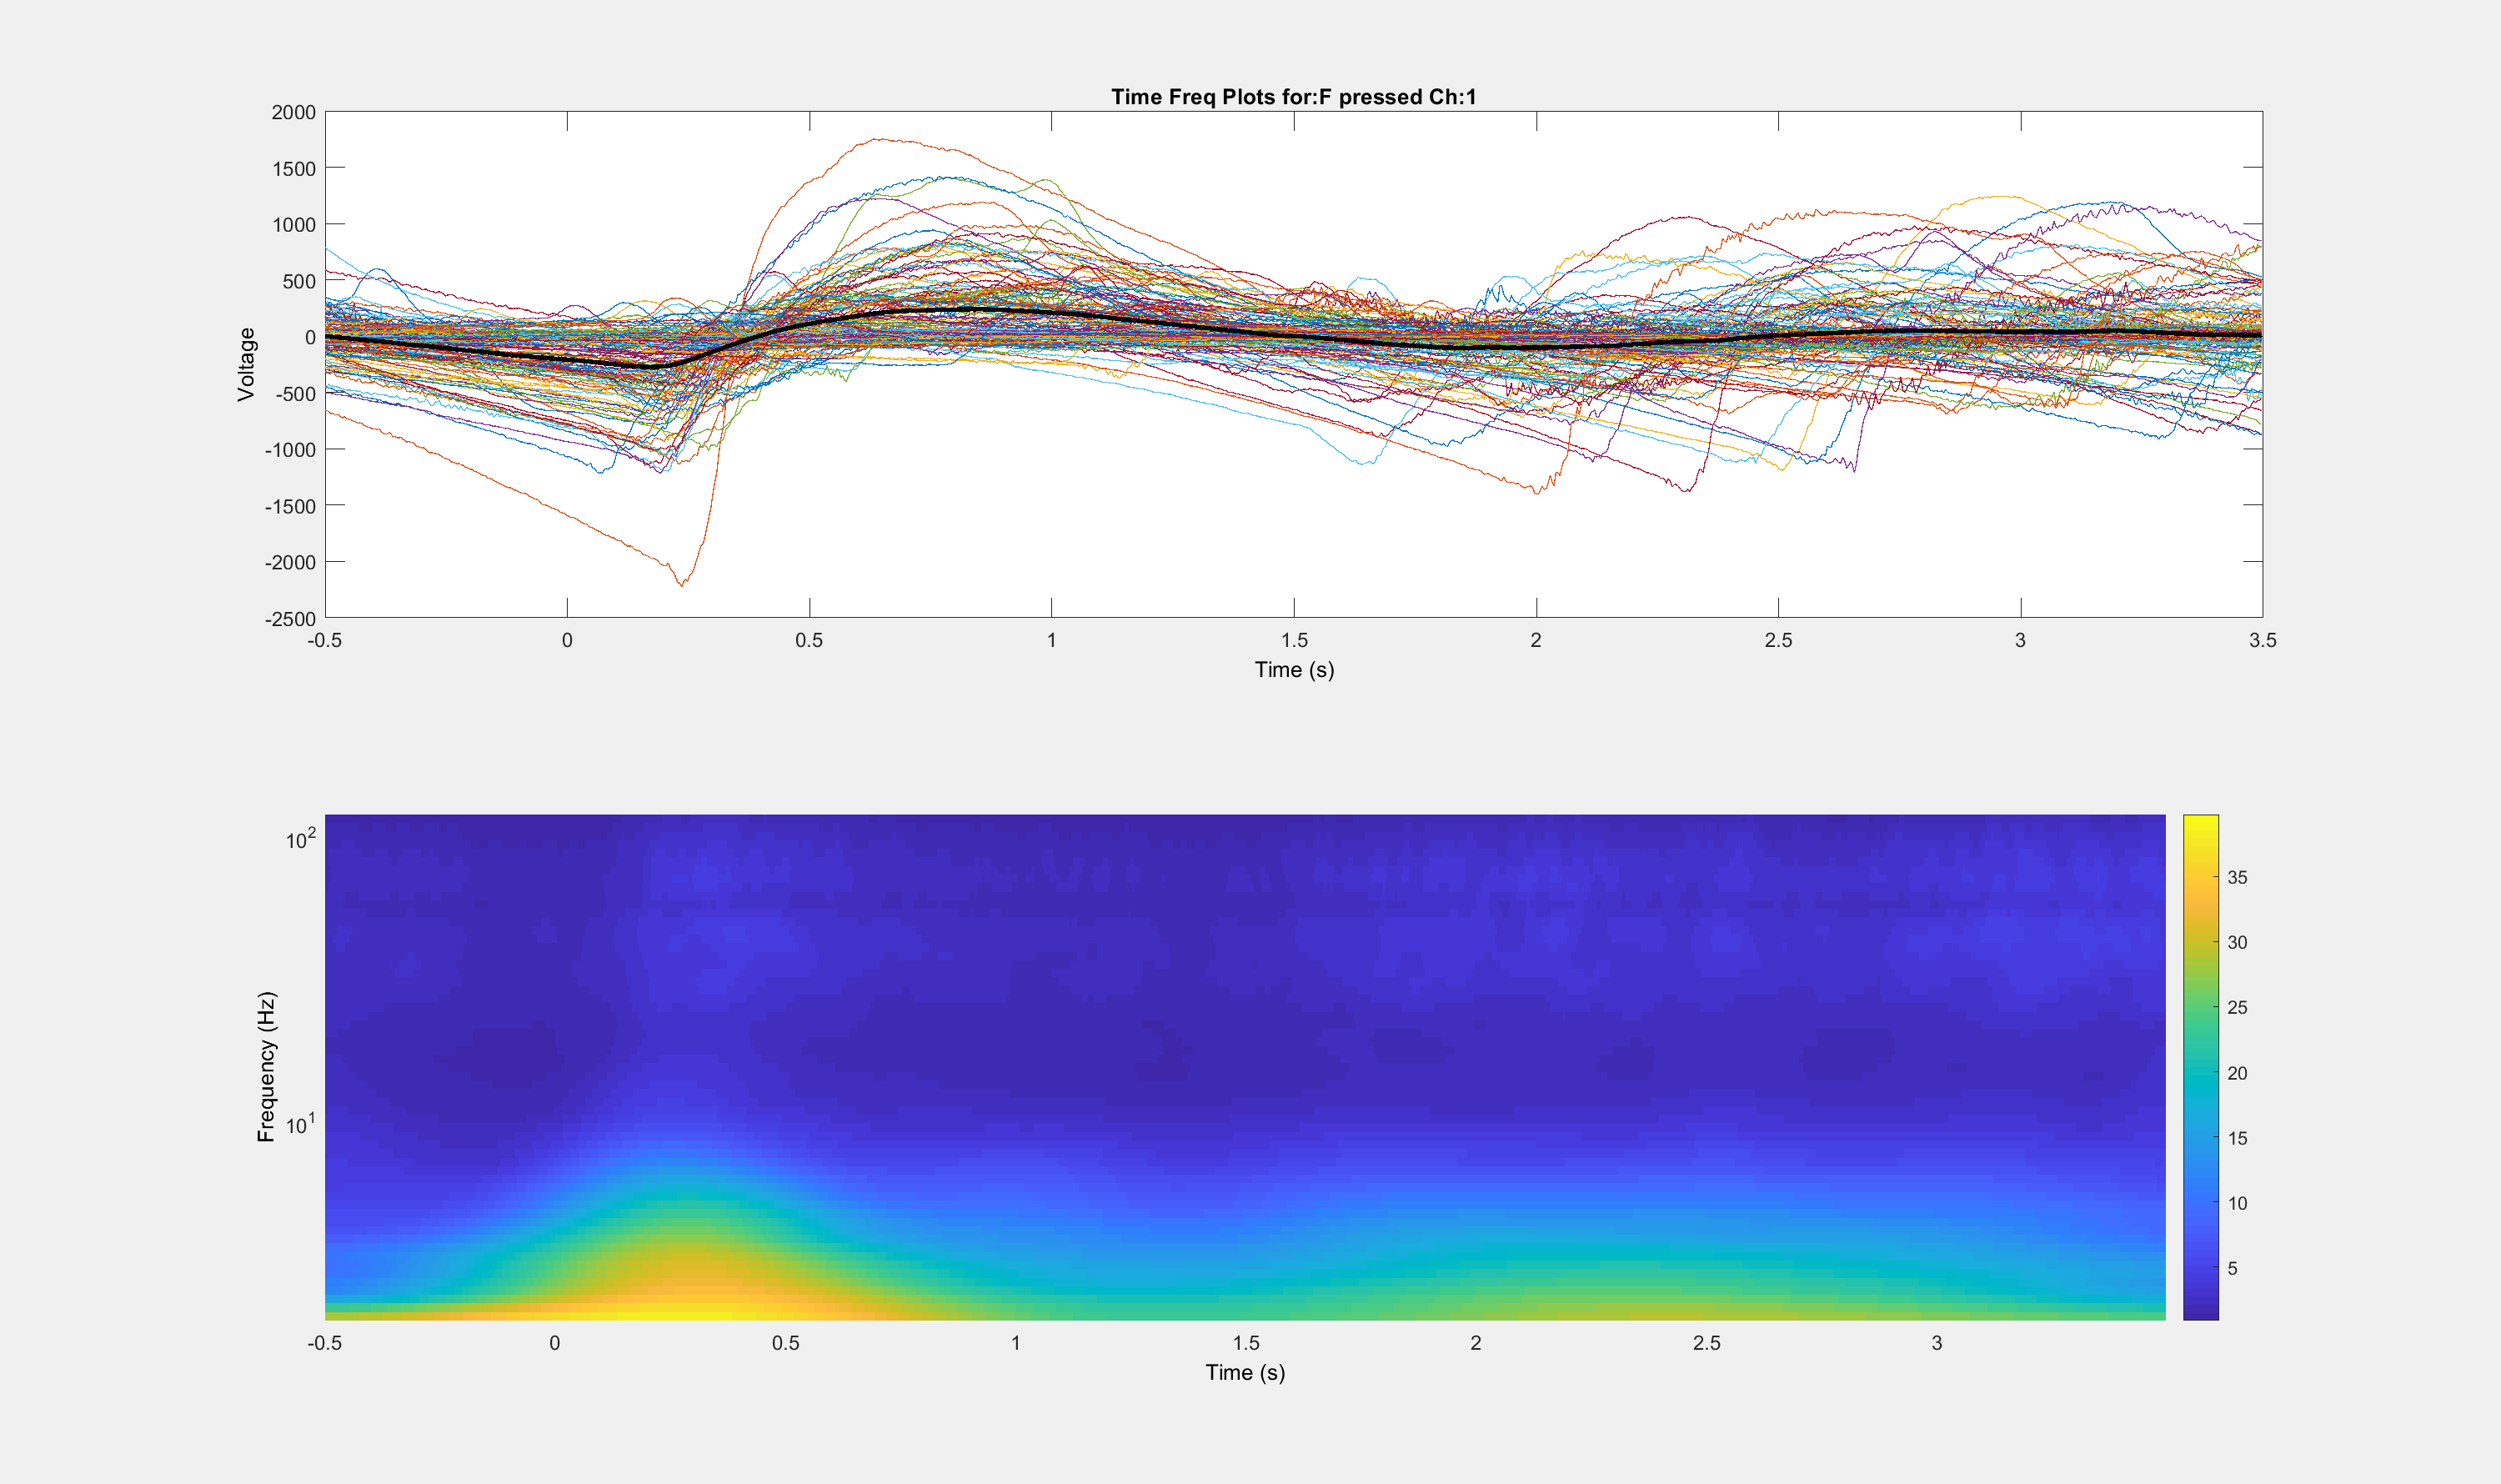

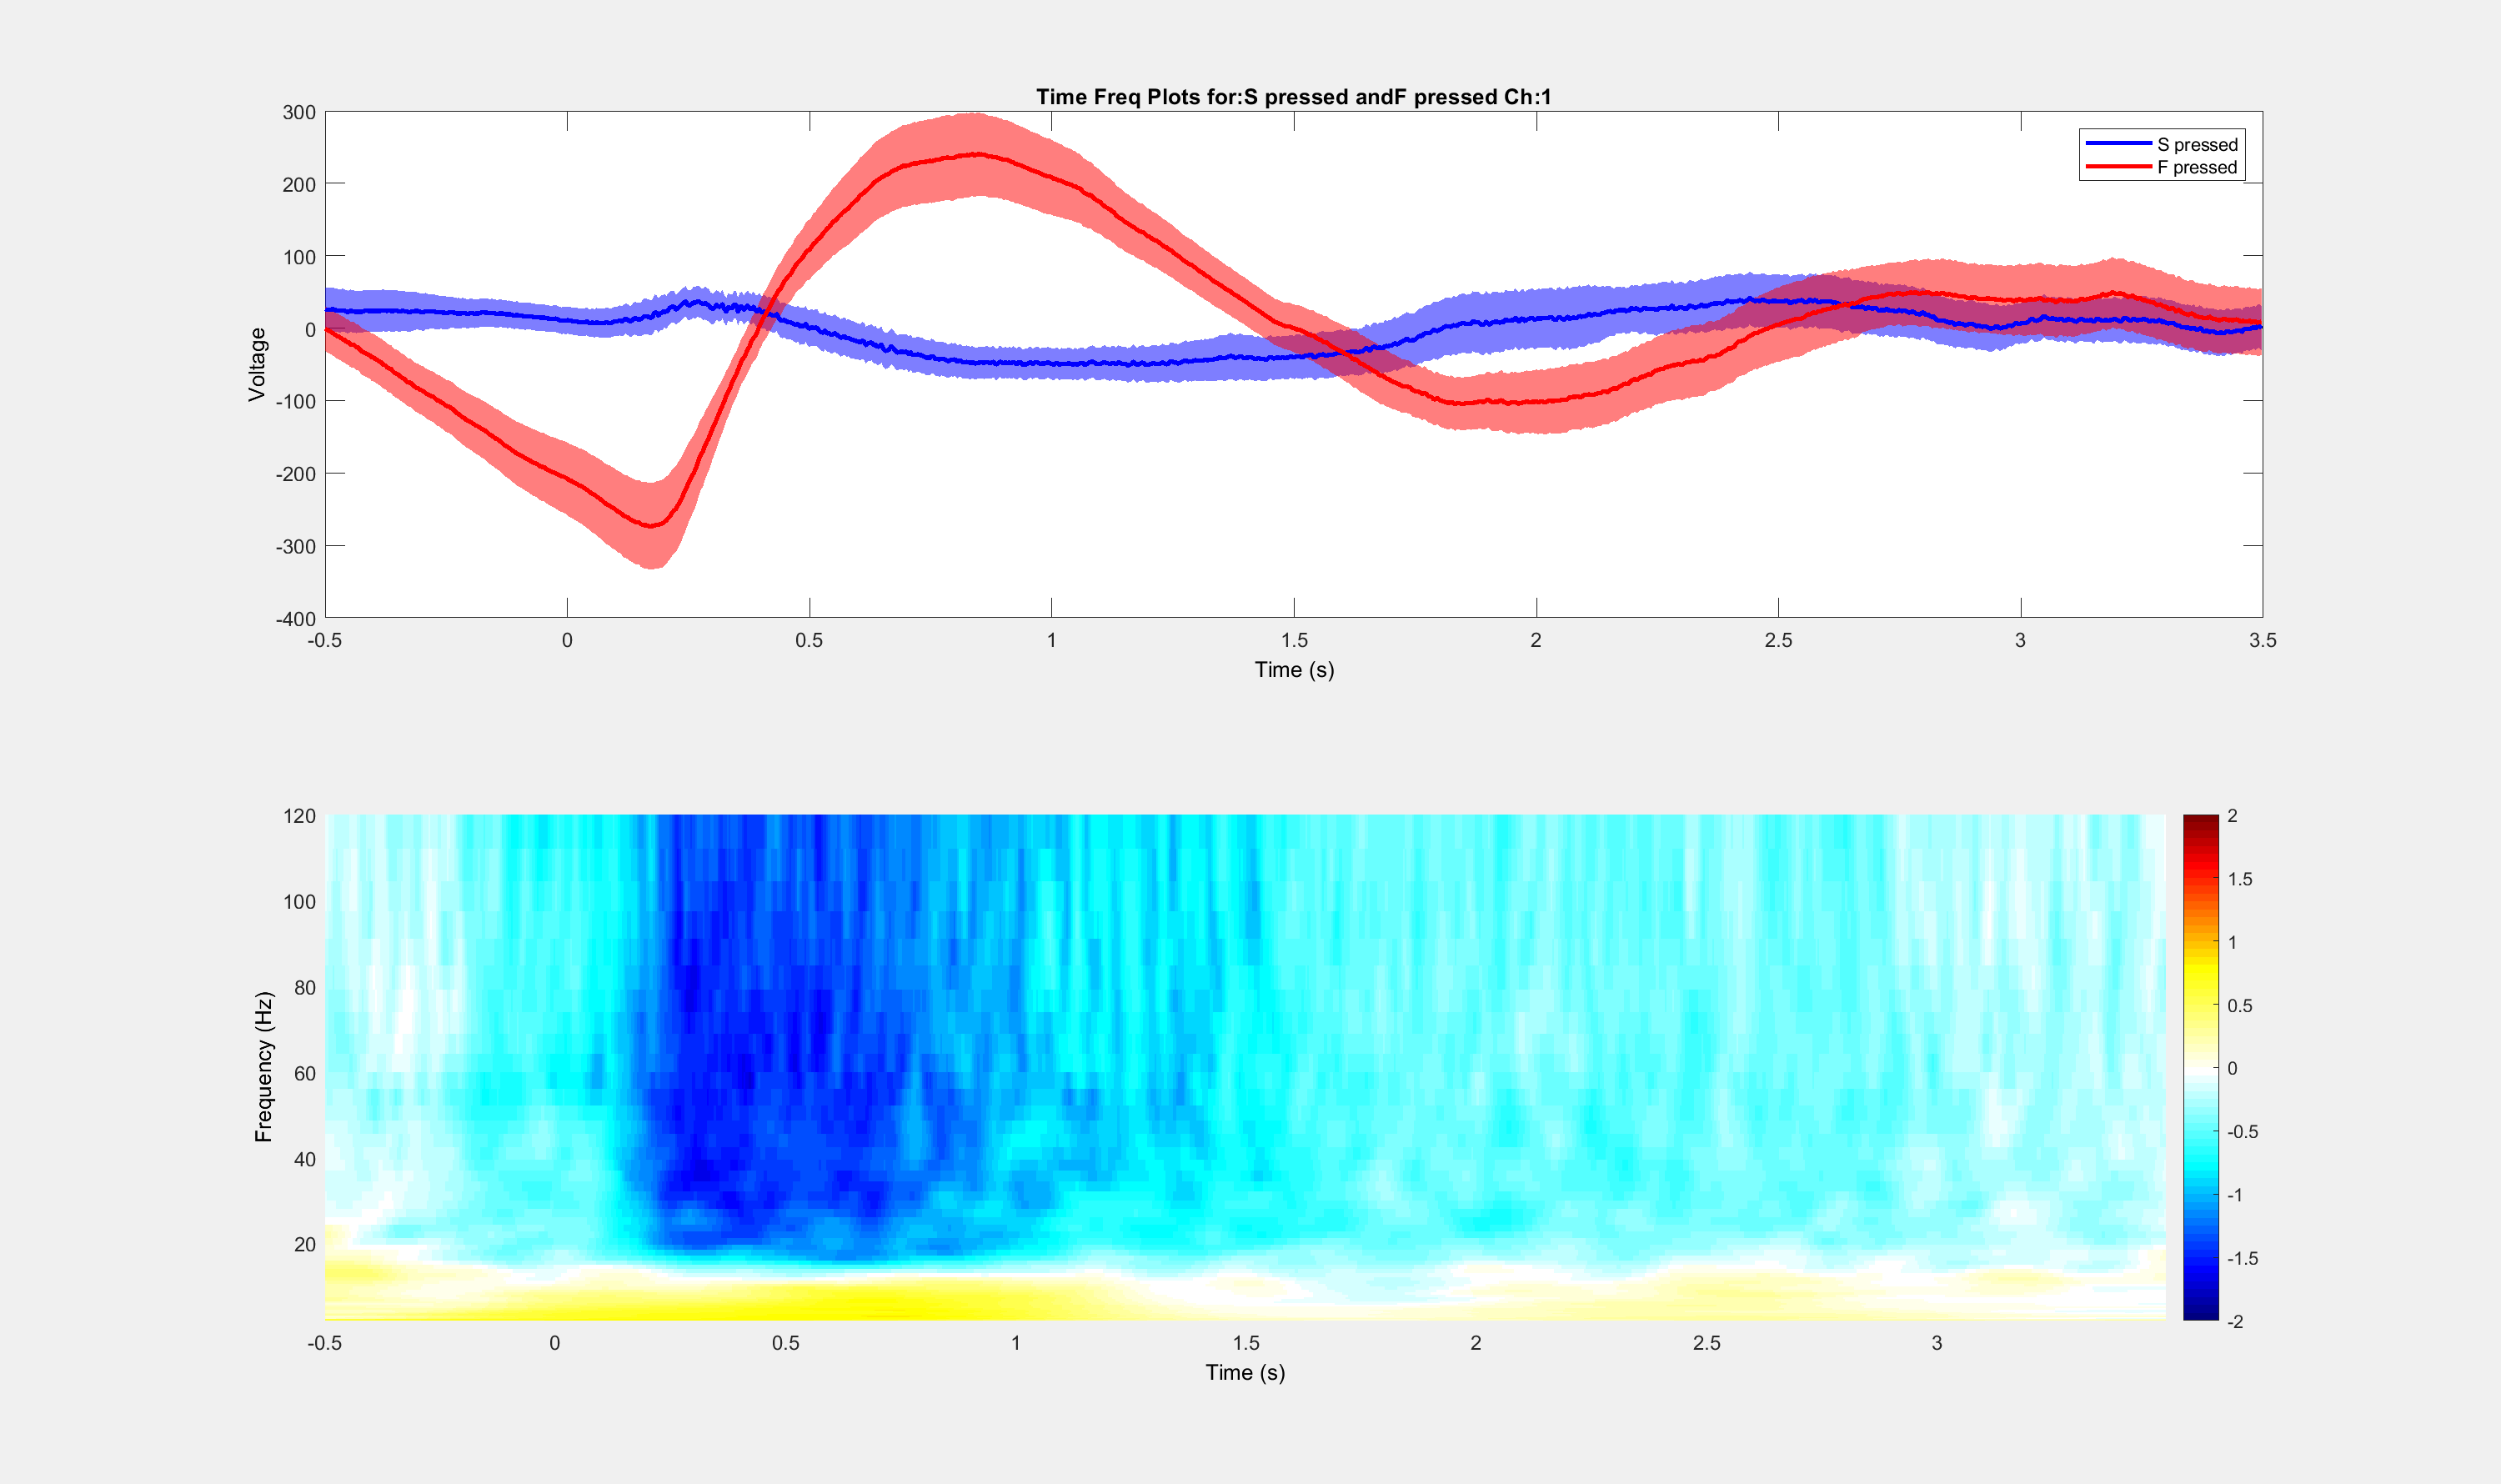

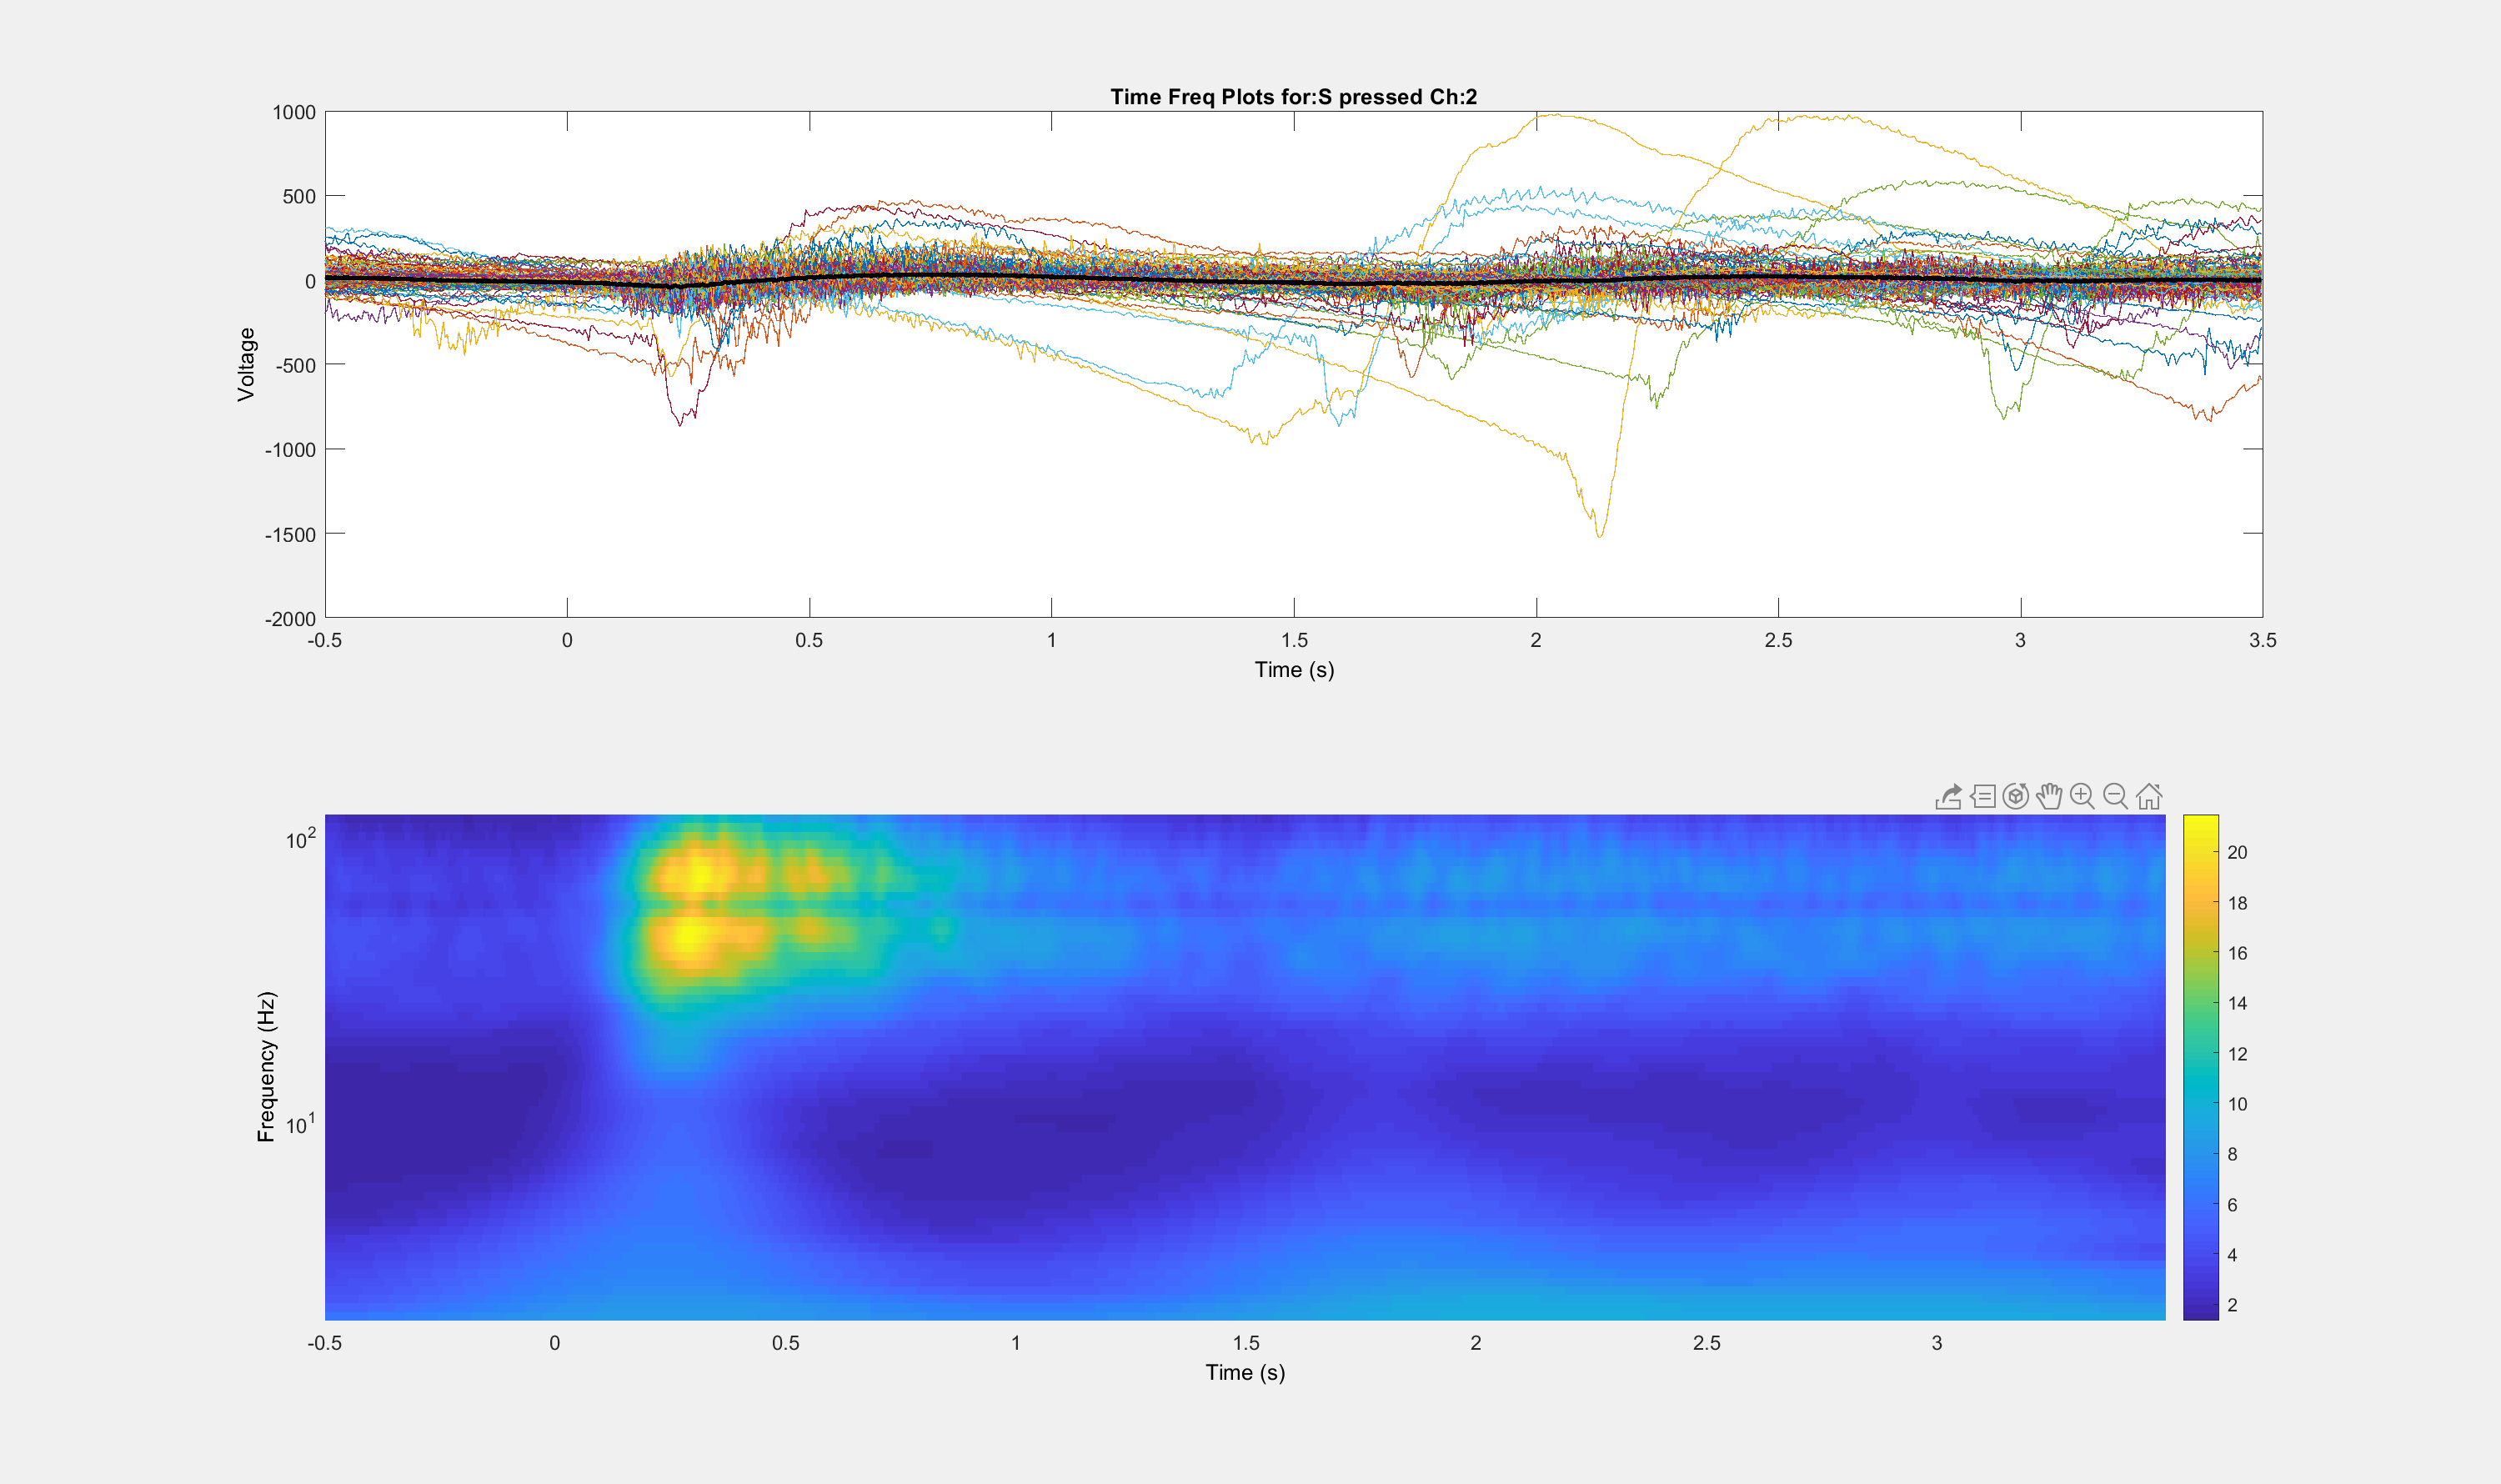

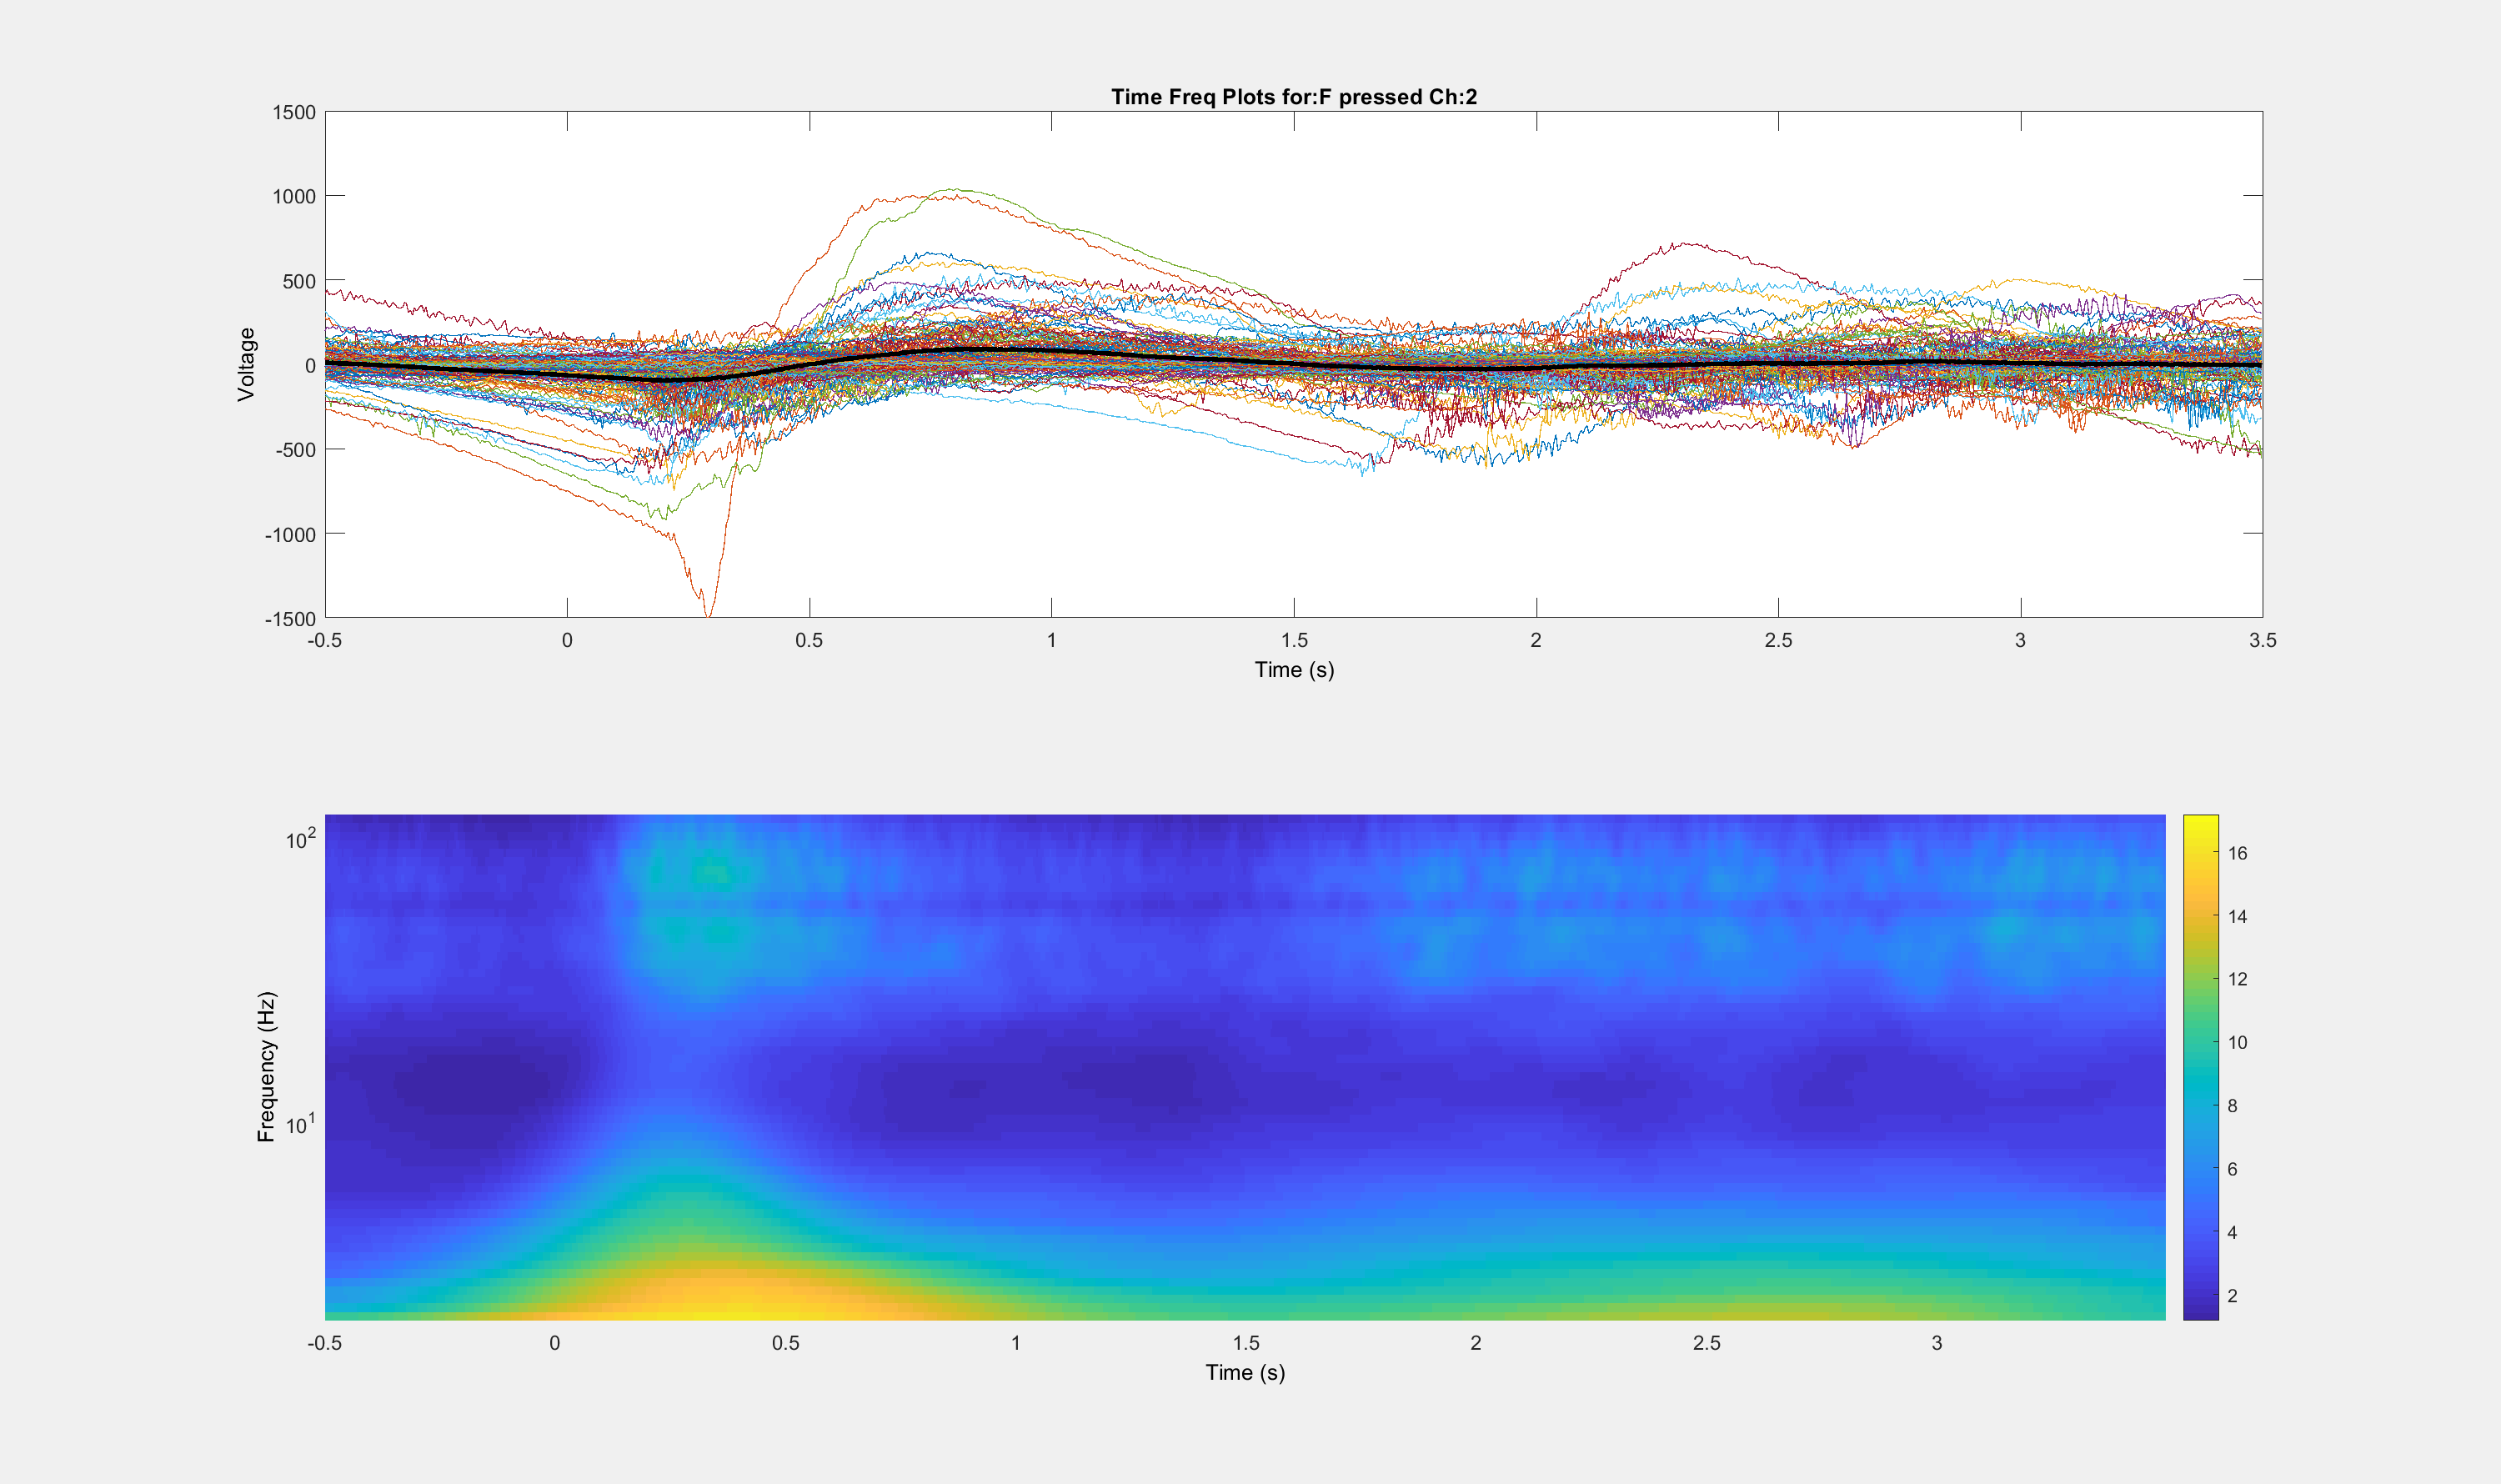

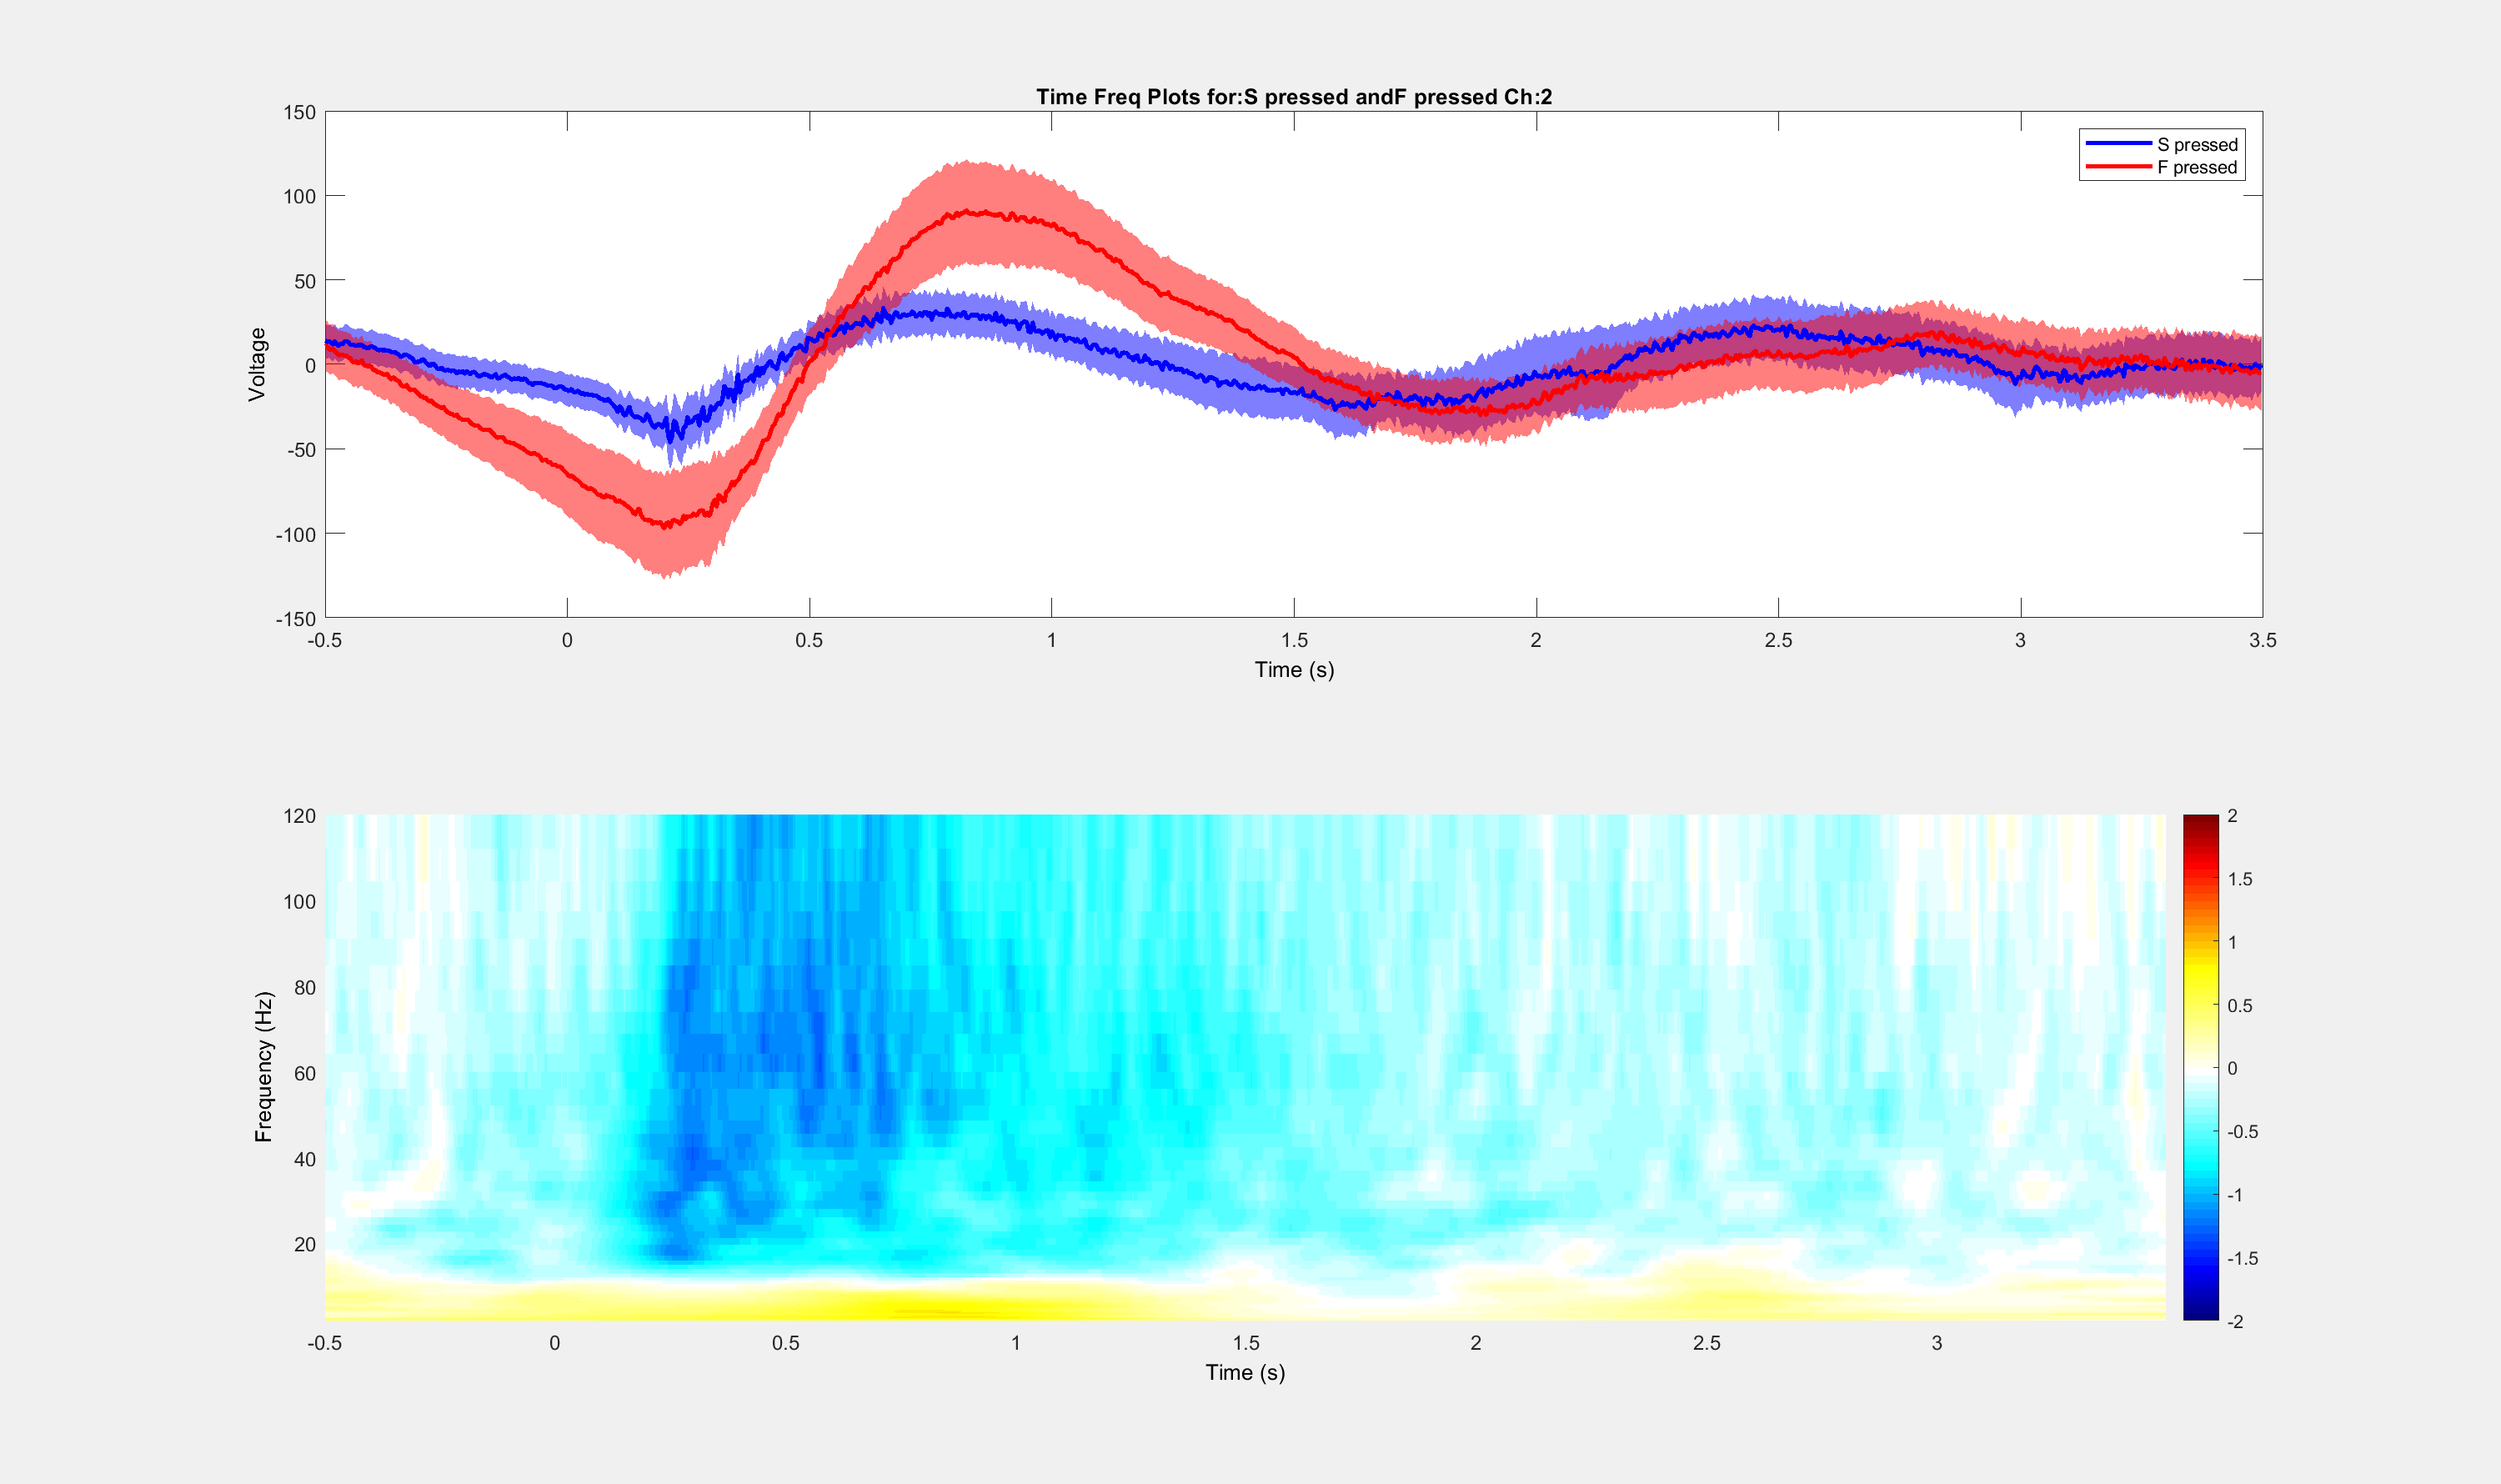

optionsforplot.individual = true;
optionsforplot.differencecond = true; 

for ch = 1:length(channels) % you can replace these if you just want to plot some
    channel = channels(ch); % in case the channel order isn't linear
    for c = 1:length(condnames)
        condname = condnames{c};
        idxtrials = find(EEG.epochlabelscat==condname);
        
        if optionsforplot.individual
            figure
            set(gcf,'Visible','on','WindowState','maximized') % This pops out the figure for easier viewing
            
            % Time series
            subplot(2,1,1)
            % Plot raw data
            plot(EEG.timessec, squeeze(EEG.data(channel,:, idxtrials))); ylabel('Voltage'); xlabel('Time (s)');
            hold on
            plot(EEG.timessec, condstruc(c,ch).meantimecourse,'k','LineWidth',2);
            title(strcat('Time Freq Plots for: ', condname,' Ch: ', num2str(channel)));
            
            %Continuous wavelet transform (average)
            subplot(2,1,2)
            surface(EEG.timessec,condstruc(c,ch).frq,condstruc(c,ch).meancfs); % moved abs to before we take th mean
            colorbar;
            axis tight
            shading flat
            xlabel('Time (s)')
            ylabel('Frequency (Hz)')
            set(gca,'yscale','log')
        end
    end 
    if optionsforplot.differencecond && length(condnames)> 1  %This does plots for 2-1 so red goes w/ plots in subplot1
        clear a1 a2 a3 pooledstd zish
        a1 = ((size(condstruc(1,ch).cfs,1)-1) .* (condstruc(1,ch).stdcfs.^2)); % weighted condition 1
        a2 = ((size(condstruc(2,ch).cfs,1)-1) .* (condstruc(2,ch).stdcfs.^2)); % weighted condition 2
        a3 = (size(condstruc(1,ch).cfs,1)+size(condstruc(2,ch).cfs,1)-2); %combined denom
        pooledstd = sqrt((a1+a2)./a3);
        zish = (condstruc(2,ch).meancfs - condstruc(1,ch).meancfs)./(pooledstd);
        
        
        figure
        set(gcf,'Visible','on','WindowState','maximized') % This pops out the figure for easier viewing
        
        % Time series
        subplot(2,1,1)
        plot(EEG.timessec, condstruc(1,ch).meantimecourse,'b','LineWidth',2);
        hold on
        plot(EEG.timessec, condstruc(2,ch).meantimecourse,'r','LineWidth',2);
        
        ciplotter(condstruc(1,ch).yCI95timecourse(:,1)+condstruc(1,ch).meantimecourse,condstruc(1,ch).yCI95timecourse(:,2)+condstruc(1,ch).meantimecourse,EEG.timessec,'b',.5);
        ciplotter(condstruc(2,ch).yCI95timecourse(:,1)+condstruc(2,ch).meantimecourse,condstruc(2,ch).yCI95timecourse(:,2)+condstruc(2,ch).meantimecourse,EEG.timessec,'r',.5);
        plot(EEG.timessec, condstruc(1,ch).meantimecourse,'b','LineWidth',2);
        plot(EEG.timessec, condstruc(2,ch).meantimecourse,'r','LineWidth',2);
        legend(condnames)
        ylabel('Voltage'); xlabel('Time (s)');
        title(strcat('Time Freq Plots for: ', condnames{1},' and ',condnames{2},' Ch: ', num2str(channel)));
        
        %Continuous wavelet transform (average)
        subplot(2,1,2)
        
        surface(EEG.timessec,condstruc(1,ch).frq,zish); % not sure if this is right log?
        colorbar; colormap(cmapwj); caxis([-2 2]); %set color of surface and colorbar/scheme axis
        axis tight; shading flat
        xlabel('Time (s)'); ylabel('Frequency (Hz)');
        %set(gca,'yscale','log')
        
        % Plot the mean power 
        %subplot(3,1,3)
    end
end

## You can ignore everything below here

Now, we're trying to develop an average across trials. This is probably not the right way to do this, but might be a reasonable starting point (need more research on appropriate way to do statistics here. 

First, create indices for the types of trials you want to look at:

condnames = {"S pressed", "F pressed"};
channel = 1;

for c = 1:length(condnames)
    condname = condnames{c}
    idxtrials = find(EEG.epochlabelscat==condname);
     
    % Mean of timecourse
    meantimecourse = mean(squeeze(EEG.data(channel,:, idxtrials)),2); 
    
    for i  = 1:length(idxtrials)
        [cfs(i,:,:),frq] = cwt(double(EEG.data(channel,:, idxtrials(i))),EEG.srate,'FrequencyLimits',[2 120]);
    end
    tms = EEG.times./1000; % time axes in seconds% (0:numel(double(EEG.data(channel,:, idxtrials(1))))-1)/EEG.srate);
    
    meancfs = squeeze(mean(abs(cfs),1));
    
    figure
    set(gcf,'Visible','on','WindowState','maximized') % This pops out the figure for easier viewing
    % Time series
    subplot(2,1,1)
    plot(EEG.timessec, squeeze(EEG.data(channel,:, idxtrials))); ylabel('Voltage'); xlabel('Time (s)');
    hold on
    plot(EEG.timessec, meantimecourse,'k','LineWidth',2);
    title(strcat('Time Freq Plots for: ', condname,' Ch: ', num2str(channel)));
    %Continuous wavelet transform (average)
    subplot(2,1,2)
    %surface(tms,frq,abs(cfs))
    surface(tms,frq,meancfs) % moved abs to before we take th mean
    colorbar;
    axis tight
    shading flat
    xlabel('Time (s)')
    ylabel('Frequency (Hz)')
    set(gca,'yscale','log')
end


Now we're going to do an even worse version of this where we try to estimate the differences between two conditions.

condnames = {"A pressed", "S pressed"};
%condnames = {"Completed1","DOWN pressed"};
channel = 2;
for c = 1:length(condnames)
    condname = condnames{c}
    idxtrials = find(EEG.epochlabelscat==condname);

    % Mean of timecourse
    condstruc(c).meantimecourse = mean(squeeze(EEG.data(channel,:, idxtrials)),2);
    condstruc(c).stdtimecourse = std(squeeze(EEG.data(channel,:,idxtrials)),0,2);  % Compute 'Standard Error Of The Mean'
    condstruc(c).semtimecourse = condstruc(c).stdtimecourse./sqrt(length(idxtrials)); 
    CI95 = tinv([0.025 0.975], length(idxtrials)-1); % Calculate 95% Probability Intervals Of t-Distribution
    condstruc(c).yCI95timecourse = bsxfun(@times, condstruc(c).semtimecourse, CI95(:)');              % Calculate 95% Confidence Intervals
    
    for i  = 1:length(idxtrials)
        [condstruc(c).cfs(i,:,:),frq] = cwt(double(EEG.data(channel,:, idxtrials(i))),EEG.srate,'FrequencyLimits',[2 120]);
    end
    tms = EEG.times./1000; % time axes in seconds% (0:numel(double(EEG.data(channel,:, idxtrials(1))))-1)/EEG.srate);
    
    condstruc(c).meancfs = squeeze(mean(abs(condstruc(c).cfs),1)); %adding an abs here to get magnitude
    condstruc(c).stdcfs = squeeze(std(abs(condstruc(c).cfs))); % may actually want to do the stdev across all time w/in a freq too
     
end

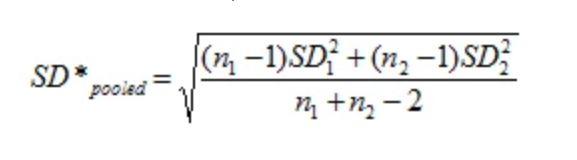

Now calculate a crappy version of a zscore or d score using the pooledweighted stdev

a1 = ((size(condstruc(1).cfs,1)-1) .* (condstruc(2).stdcfs.^2));
a2 = ((size(condstruc(2).cfs,1)-1) .* (condstruc(2).stdcfs.^2));
a3 = (size(condstruc(2).cfs,1)+size(condstruc(2).cfs,1)-2);
pooledstd = sqrt((a1+a2)./a3);
zish = (condstruc(2).meancfs - condstruc(1).meancfs)./(pooledstd);


figure
set(gcf,'Visible','on','WindowState','maximized') % This pops out the figure for easier viewing
% Time series
subplot(2,1,1)
plot(EEG.timessec, condstruc(1).meantimecourse,'b','LineWidth',2);
hold on
plot(EEG.timessec, condstruc(2).meantimecourse,'r','LineWidth',2);

ciplotter(condstruc(1).yCI95timecourse(:,1)+condstruc(1).meantimecourse,condstruc(1).yCI95timecourse(:,2)+condstruc(1).meantimecourse,EEG.timessec,'b',.5);
ciplotter(condstruc(2).yCI95timecourse(:,1)+condstruc(2).meantimecourse,condstruc(2).yCI95timecourse(:,2)+condstruc(2).meantimecourse,EEG.timessec,'r',.5);
plot(EEG.timessec, condstruc(1).meantimecourse,'b','LineWidth',2);
plot(EEG.timessec, condstruc(2).meantimecourse,'r','LineWidth',2);
legend(condnames)
ylabel('Voltage'); xlabel('Time (s)');
title(strcat('Time Freq Plots for: ', condnames{1},' and ',condnames{2},' Ch: ', num2str(channel)));
%Continuous wavelet transform (average)
subplot(2,1,2)
%surface(tms,frq,abs(cfs))
%surface(tms,frq,abs(meancfs))
surface(tms,frq,zish); % not sure if this is right log?
colorbar;
colormap(cmapwj);
axis tight
shading flat
xlabel('Time (s)')
ylabel('Frequency (Hz)')
caxis([-2 2])
%set(gca,'yscale','log')

% Plot the mean power 
%subplot(3,1,3)




**This space is to play around with the number of parameters for the cwt**

condnames = {"S pressed","F pressed"};
channel = 1;
clear condstruc idxtrials
for c = 1:length(condnames)
    condname = condnames{c}
    idxtrials = find(EEG.epochlabelscat==condname);

    % Mean of timecourse
    condstruc(c).meantimecourse = mean(squeeze(EEG.data(channel,:, idxtrials)),2);
    condstruc(c).stdtimecourse = std(squeeze(EEG.data(channel,:,idxtrials)),0,2);  % Compute 'Standard Error Of The Mean'
    condstruc(c).semtimecourse = condstruc(c).stdtimecourse./sqrt(length(idxtrials)); 
    CI95 = tinv([0.025 0.975], length(idxtrials)-1); % Calculate 95% Probability Intervals Of t-Distribution
    condstruc(c).yCI95timecourse = bsxfun(@times, condstruc(c).semtimecourse, CI95(:)');              % Calculate 95% Confidence Intervals
    
    for i  = 1:length(idxtrials)
        [condstruc(c).cfs(i,:,:),frq] = cwt(double(EEG.data(channel,:, idxtrials(i))),EEG.srate,...
            'TimeBandwidth',4); %'FrequencyLimits',[2 120],
    end
    tms = EEG.times./1000; % time axes in seconds% (0:numel(double(EEG.data(channel,:, idxtrials(1))))-1)/EEG.srate);
    
    condstruc(c).meancfs = squeeze(mean(abs(condstruc(c).cfs),1)); %adding an abs here to get magnitude
    condstruc(c).stdcfs = squeeze(std(abs(condstruc(c).cfs))); % may actually want to do the stdev across all time w/in a freq too
     
end

a1 = ((size(condstruc(1).cfs,1)-1) .* (condstruc(2).stdcfs.^2));
a2 = ((size(condstruc(2).cfs,1)-1) .* (condstruc(2).stdcfs.^2));
a3 = (size(condstruc(2).cfs,1)+size(condstruc(2).cfs,1)-2);
pooledstd = sqrt((a1+a2)./a3);
zish = (condstruc(2).meancfs - condstruc(1).meancfs)./(pooledstd);

%Continuous wavelet transform (average)
figure 
set(gcf,'Visible','on','WindowState','maximized') % This pops out the figure for easier viewing
surface(tms,frq,zish); % not sure if this is right log?
colorbar;
colormap(cmapwj);
title(strcat('Time Freq Plots for: ', condnames{1},' and ',condnames{2},' Ch: ', num2str(channel)));
axis tight
shading flat
xlabel('Time (s)')
ylabel('Frequency (Hz)')
caxis([-2 2])


### More stuff down here that can be an introduction and some single trials

%conditions = ["F pressed","S pressed"];
conditions = ["Completed4","GameOver"];

condcolors = {'b','r'}; %make these blue and red lines, must be at least as long as conditions
channel = 2;

figure
for c = 1:length(conditions)
    idx = find(EEG.epochlabelscat==conditions{c});
    plot(EEG.times, squeeze(EEG.data(channel,:,idx)),condcolors{c})
    hold on;
%     for ep = idx
%         if length(EEG.epoch(ep).eventlatency) > 2
%             xline(EEG.epoch(ep).eventlatency{3},condcolors{c});
%         end
%     end
end
hold off

Play around with signal processing

% Plot the power vs frequency
%pspectrum(squeeze(EEG.data(channel,:,5)),EEG.times./1000) %./1000 to convert to seconds

Make a plot for a single trial

channel = 2;
trial = 1739;%find(EEG.epochlabelscat=="Completed4",1); 
figure
set(gcf,'Visible','on','WindowState','maximized') % This pops out the figure for easier viewing
subplot(3,1,1)
plot(EEG.timessec, squeeze(EEG.data(channel,:,trial))); ylabel('Voltage'); xlabel('Time (s)');
title(strcat('Time Freq Plots for Ch: ', num2str(channel),' and Trial: ', num2str(trial)));
subplot(3,1,2)
pspectrum(squeeze(EEG.data(channel,:,trial)),EEG.timessec,'spectrogram'); 
caxis([-50 20])
subplot(3,1,3)
pspectrum(squeeze(EEG.data(channel,:,trial)),EEG.timessec); 
hold off;

Use a continuous wavelet transform to get a deeper view

figure;
set(gcf,'Visible','on','WindowState','maximized','Name',strcat('Ch: ', num2str(channel),' and Trial: ', num2str(trial))) % This pops out the figure for easier viewing
cwt(double(squeeze(EEG.data(channel,:,trial))),EEG.srate);